%https://www.mathworks.com/help/matlab/ref/fft.html

Fs = 1000; % Sampling freq                  
T = 1/Fs;                    
L = 8000; % signal length
t = (0:L-1)*T; % Time
%t= 0:0.001:8
%Task i)

syms v(t)

v(t) = abs(sin(pi*t)) + 2*sin(3*pi*t) + 3*sin(6*pi*t)

$$v(t) = 2\,\sin\left(3\,\pi \,t\right)+3\,\sin\left(6\,\pi \,t\right)+\left|\sin\left(\pi \,t\right)\right|$$

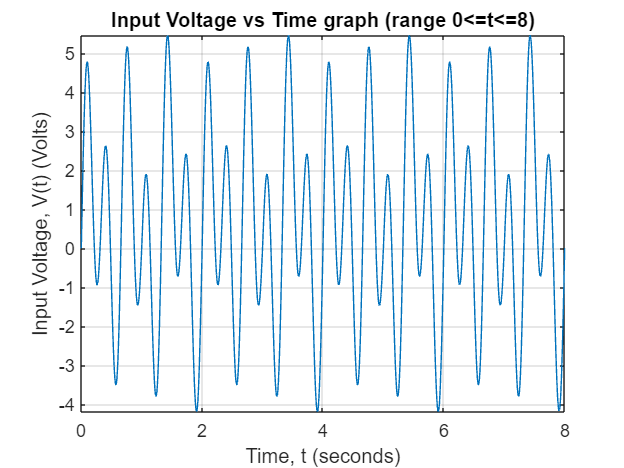

fplot(t,v, [0,8])
xlabel('Time, t (seconds)')
ylabel('Input Voltage, V(t) (Volts)')
grid on
title('Input Voltage vs Time graph (range 0<=t<=8)')


%task ii)f(s)

%fastf=fft(v)



%plot(Fs/L*(0:L-1),abs(v_f),"LineWidth",3)
%plot(Fs/L*(-L/2:L/2-1),abs(fftshift(v_f)),"LineWidth",3)
f = 1:8000

f =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


plot(fft(v),t, "LineWidth",3)

Error using indexing
Indexing values must be positive integers, logicals, or symbolic variables. For 'symfun' data type, indexing means evaluating the function for the given value. See also 'subs'.

Related documentation

xlabel('Frequency (Hz)')
ylabel('FFT')
grid on
title('fft vs Frequency graph')